# Aproximación de primer orden de operadores fraccionarios con el método de Prony

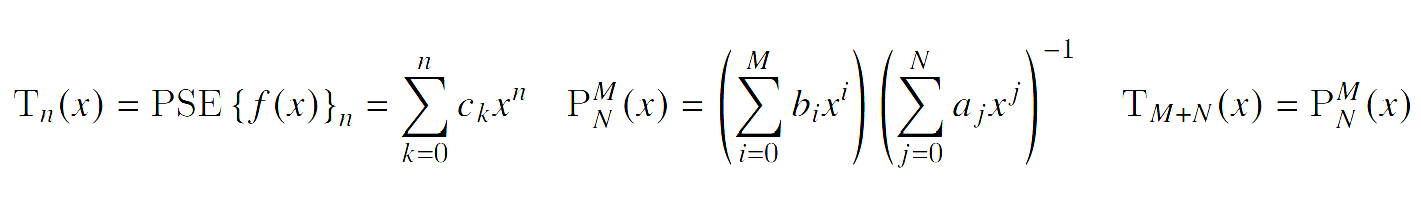

MM = 9;
NN = 9;
L = 500;
orden = -0.5;
periodo = 0.01;
tipo = 0.875;

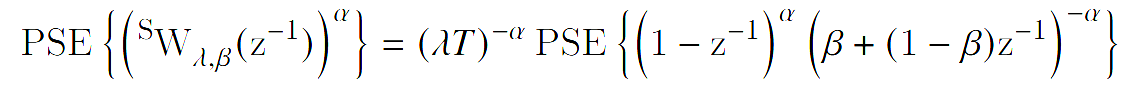

syms x;
% Generacion de coeficientes de MacLaurin
h_expr = (1/periodo * (1 - x) / (tipo +(1 - tipo)*x))^orden;
h_series = taylor(h_expr, x, 'Order', L); %es muy lento 
h_coeffs = fliplr(coeffs(h_series, 'All'));

h = double(h_coeffs);

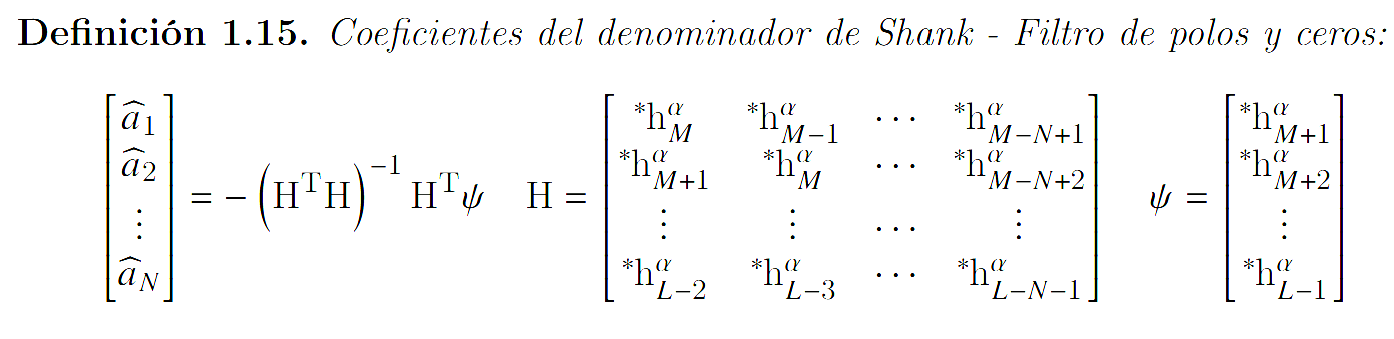

h21 = h(MM+2:L)';
H2 = toeplitz(h, zeros(1, NN));

H2 = H2(MM+1:L-1,:);
aa = (H2' * H2) \ (-H2' * h21);

aa = [1;aa];

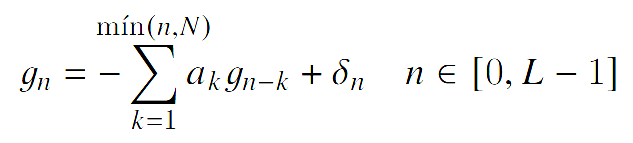

ff = [1, zeros(1, L-1)];
gg = filter(1, aa, ff);

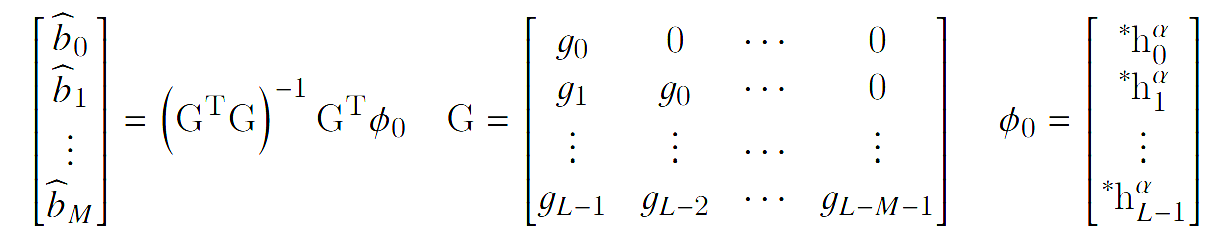

GG = toeplitz(gg,[gg(1) zeros(1,MM)]);
bb = (GG' * GG) \ (GG' * h');

## Simulacion

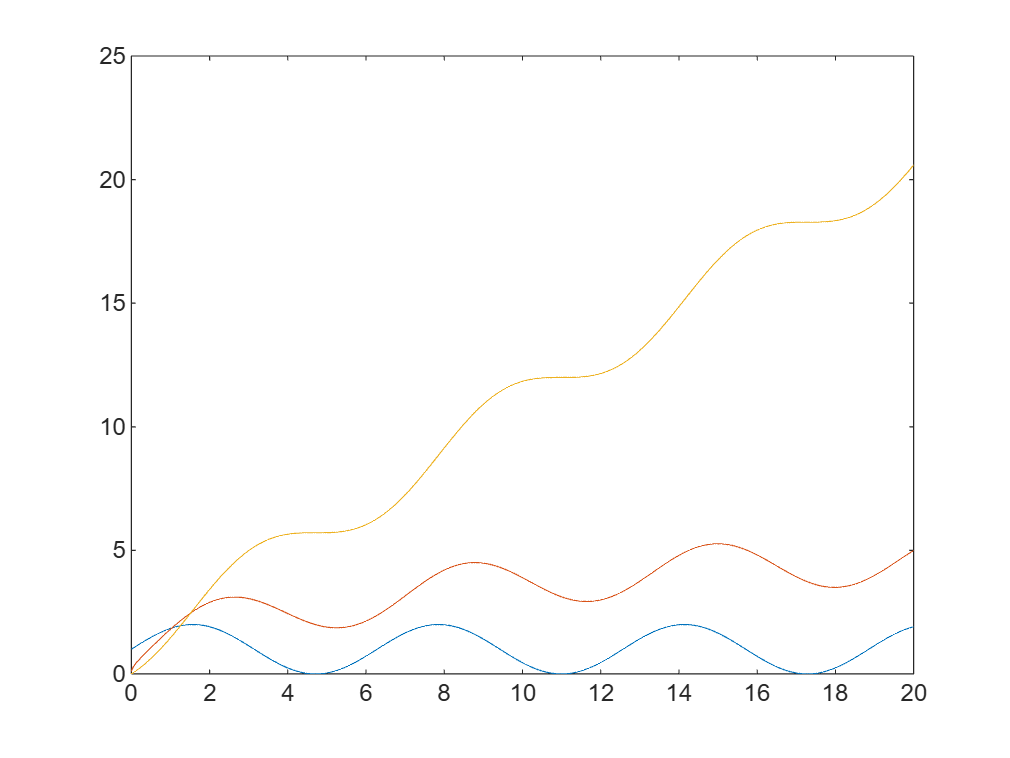

t = 0:0.01:20;
f = sin(t)+1;
filtro = filter(bb,aa,f);
filtro2 = cumtrapz(t,f);
plot(t,f,t,filtro,t,filtro2)